# Loading the signal

% Load the audio files
[x1, f1] = audioread('Short_BBCArabic2.wav'); 
[x2, f2] = audioread('Short_SkyNewsArabia.wav');
[x3, f3] = audioread('Short_FM9090.wav');
[x4, f4] = audioread('Short_QuranPalestine.wav');
[x5, f5] = audioread('Short_RussianVoice.wav');

% Choose a common sampling frequency (e.g., maximum of all sampling frequencies)
Fs = max([f1, f2, f3, f4, f5]);

% Resample each signal to the common sampling frequency
x1 = resample(x1, Fs, f1);
x2 = resample(x2, Fs, f2);
x3 = resample(x3, Fs, f3);
x4 = resample(x4, Fs, f4);
x5 = resample(x5, Fs, f5);

% Calculate the duration of the first signal
SignalDuration = length(x1) / Fs;

## Combine Stereo channels

monoSignal1 = x1(:, 1) + x1(:, 2);
monoSignal2 = x2(:, 1) + x2(:, 2);
monoSignal3 = x3(:, 1) + x3(:, 2);
monoSignal4 = x4(:, 1) + x4(:, 2);
monoSignal5 = x5(:, 1) + x5(:, 2);


## Padding signals

% Calculate the maximum length
maxLength = max([length(monoSignal1), length(monoSignal2), length(monoSignal3), length(monoSignal4), length(monoSignal5)]);

% Pad the signals with zeros
monoSignal1 = [monoSignal1; zeros(maxLength - length(monoSignal1), 1)];
monoSignal2 = [monoSignal2; zeros(maxLength - length(monoSignal2), 1)];
monoSignal3 = [monoSignal3; zeros(maxLength - length(monoSignal3), 1)];
monoSignal4 = [monoSignal4; zeros(maxLength - length(monoSignal4), 1)];
monoSignal5 = [monoSignal5; zeros(maxLength - length(monoSignal5), 1)];

## PLOTTING SIGNALS

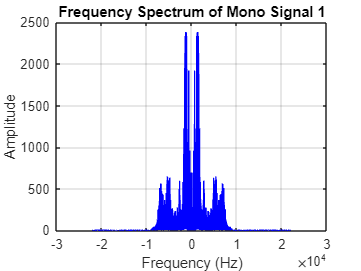

% Compute the FFT and frequency vector for each signal
freq = (-maxLength/2:maxLength/2-1) * (Fs / maxLength); % Frequency vector

% Compute the FFT for each mono signal
spectrum1 = fftshift(abs(fft(monoSignal1)));
spectrum2 = fftshift(abs(fft(monoSignal2)));
spectrum3 = fftshift(abs(fft(monoSignal3)));
spectrum4 = fftshift(abs(fft(monoSignal4)));
spectrum5 = fftshift(abs(fft(monoSignal5)));

% Spectrum of Signal 1
figure;
plot(freq, spectrum1, 'b');
xlabel('Frequency (Hz)');
ylabel('Amplitude');
title('Frequency Spectrum of Mono Signal 1');
grid on;

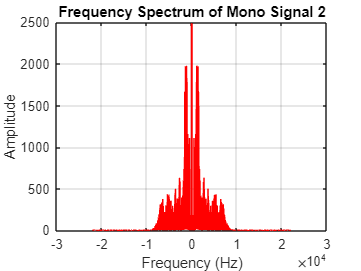


% Spectrum of Signal 2
figure;
plot(freq, spectrum2, 'r');
xlabel('Frequency (Hz)');
ylabel('Amplitude');
title('Frequency Spectrum of Mono Signal 2');
grid on;

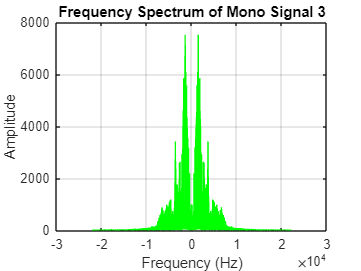


% Spectrum of Signal 3
figure;
plot(freq, spectrum3, 'g');
xlabel('Frequency (Hz)');
ylabel('Amplitude');
title('Frequency Spectrum of Mono Signal 3');
grid on;

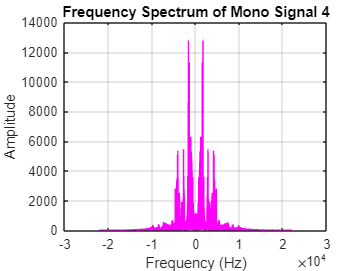


% Spectrum of Signal 4
figure;
plot(freq, spectrum4, 'm');
xlabel('Frequency (Hz)');
ylabel('Amplitude');
title('Frequency Spectrum of Mono Signal 4');
grid on;

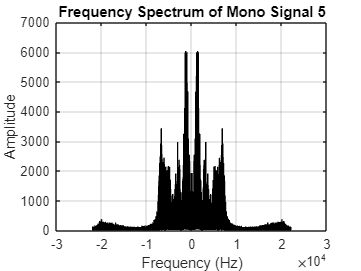


% Spectrum of Signal 5
figure;
plot(freq, spectrum5, 'k');
xlabel('Frequency (Hz)');
ylabel('Amplitude');
title('Frequency Spectrum of Mono Signal 5');
grid on;

## Amplitude Modulation

% Carrier frequencies 
fc1 = 100000; 
fc2 = 150000; 
fc3 = 200000; 
fc4 = 250000; 
fc5 = 300000; 

%The sampling frequency is smaller the the carrier frequency
%Interp multiplies the sampling freq by 15
monoSignal1_HighFs = interp(monoSignal1, 15);
monoSignal2_HighFs = interp(monoSignal2, 15);
monoSignal3_HighFs = interp(monoSignal3, 15);
monoSignal4_HighFs = interp(monoSignal4, 15);
monoSignal5_HighFs = interp(monoSignal5, 15);

% the carrier frequency must be higher than the highest frequency... 
% in the baseband signal to ensure proper modulation.
Fs_new=Fs*15;
t= 0 : 1/Fs_new : SignalDuration-(1/Fs_new);

% Generate carriers
carrier1 = cos(2 * pi * fc1 * t'); 
carrier2 = cos(2 * pi * fc2 * t'); 
carrier3 = cos(2 * pi * fc3 * t'); 
carrier4 = cos(2 * pi * fc4 * t'); 
carrier5 = cos(2 * pi * fc5 * t'); 

% DSB-SC modulation
modulatedSignal1 = monoSignal1_HighFs .* carrier1; 
modulatedSignal2 = monoSignal2_HighFs .* carrier2; 
modulatedSignal3 = monoSignal3_HighFs .* carrier3; 
modulatedSignal4 = monoSignal4_HighFs .* carrier4;
modulatedSignal5 = monoSignal5_HighFs .* carrier5; 

## Plot the modulated signals

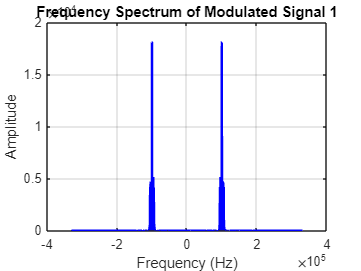

% Compute the FFT and frequency vector for modulated signals
N_modulated = length(modulatedSignal1); % All modulated signals have the same length
freq_modulated = (-N_modulated/2:N_modulated/2-1) * (Fs_new / N_modulated); % Frequency vector

% Compute the FFT for each modulated signal
spectrumMod1 = fftshift(abs(fft(modulatedSignal1)));
spectrumMod2 = fftshift(abs(fft(modulatedSignal2)));
spectrumMod3 = fftshift(abs(fft(modulatedSignal3)));
spectrumMod4 = fftshift(abs(fft(modulatedSignal4)));
spectrumMod5 = fftshift(abs(fft(modulatedSignal5)));

% Plot each modulated signal's spectrum on a separate figure
% Spectrum of Modulated Signal 1
figure;
plot(freq_modulated, spectrumMod1, 'b');
xlabel('Frequency (Hz)');
ylabel('Amplitude');
title('Frequency Spectrum of Modulated Signal 1');
grid on;

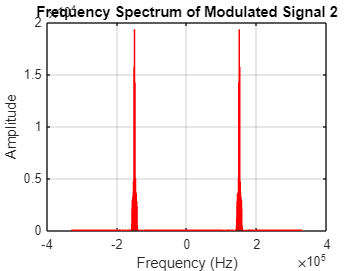


% Spectrum of Modulated Signal 2
figure;
plot(freq_modulated, spectrumMod2, 'r');
xlabel('Frequency (Hz)');
ylabel('Amplitude');
title('Frequency Spectrum of Modulated Signal 2');
grid on;

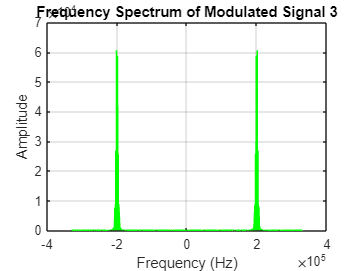


% Spectrum of Modulated Signal 3
figure;
plot(freq_modulated, spectrumMod3, 'g');
xlabel('Frequency (Hz)');
ylabel('Amplitude');
title('Frequency Spectrum of Modulated Signal 3');
grid on;

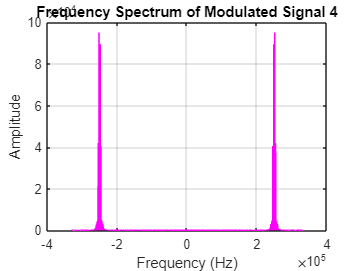


% Spectrum of Modulated Signal 4
figure;
plot(freq_modulated, spectrumMod4, 'm');
xlabel('Frequency (Hz)');
ylabel('Amplitude');
title('Frequency Spectrum of Modulated Signal 4');
grid on;

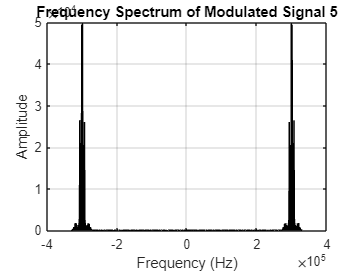


% Spectrum of Modulated Signal 5
figure;
plot(freq_modulated, spectrumMod5, 'k');
xlabel('Frequency (Hz)');
ylabel('Amplitude');
title('Frequency Spectrum of Modulated Signal 5');
grid on;

## Plot Sent signal

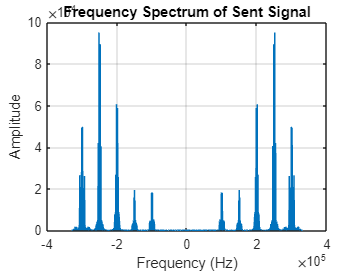

Sent_Signal=modulatedSignal1+modulatedSignal2+modulatedSignal3+modulatedSignal4+modulatedSignal5;

% Compute the spectrum of the Sent signal
N = length(Sent_Signal); 
freq = (-N/2:N/2-1) * (Fs_new / N); 
spectrumsent = fftshift(abs(fft(Sent_Signal))); 

% Plot the Sent signal in the frequency domain
figure;
plot(freq, spectrumsent);
xlabel('Frequency (Hz)');
ylabel('Amplitude');
title('Frequency Spectrum of Sent Signal');
grid on;

## BPF 1

% parameters
n = 0; %n=0 for first signal & n=1 for second signal and so on
fc = 100000+(50000*n); 
% i put signal 1 has smallest bw then signal 2 and so on
% so that also bw can be controlled using n like the fc
bw = 9000+(1500*n);  

% pass edges
F_pass1 = fc - bw/2; 
F_pass2 = fc + bw/2; 

% Stopband edges
F_stop1 = F_pass1 - bw/4; 
F_stop2 = F_pass2 + bw/4; 

% Create the filter specification object
bpSpec = fdesign.bandpass('Fst1,Fp1,Fp2,Fst2,Ast1,Ap,Ast2', F_stop1, F_pass1, F_pass2, F_stop2, 70, 1, 70, Fs_new);

BandPassFilter = design(bpSpec, 'equiripple'); % FIR filter using equiripple design

%fvtool(BandPassFilter); 

## Plot Filtered signal

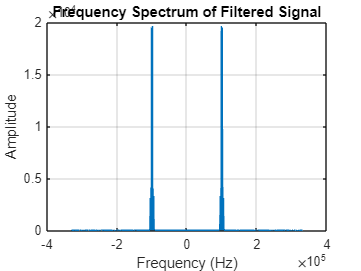

Filtered_Signal1 = filter(BandPassFilter, Sent_Signal);
% Compute the spectrum of the filtered signal
N = length(Filtered_Signal1); 
freq = (-N/2:N/2-1) * (Fs_new / N); 
spectrumFiltered1 = fftshift(abs(fft(Filtered_Signal1))); 

% Plot the filtered signal in the frequency domain
figure;
plot(freq, spectrumFiltered1);
xlabel('Frequency (Hz)');
ylabel('Amplitude');
title('Frequency Spectrum of Filtered Signal');
grid on;

## Oscillator to shift to Wif

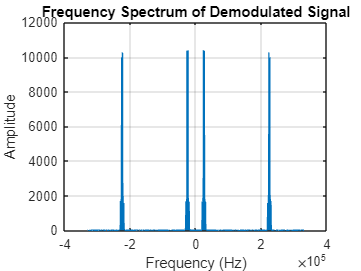

Wif = 25000;
Wosc1 = Wif + ((n*50000) + 100000 );
carrier_osc1 = cos(2*pi*Wosc1 * t');

Demodulated_Signal = Filtered_Signal1 .* carrier_osc1;

% Compute the FFT of the demodulated signal
N = length(Demodulated_Signal); 
freq = (-N/2:N/2-1) * (Fs_new / N); 
spectrumDemodulated = fftshift(abs(fft(Demodulated_Signal))); 

% Plot the demodulated signal in the frequency domain
figure;
plot(freq, spectrumDemodulated);
xlabel('Frequency (Hz)');
ylabel('Amplitude');
title('Frequency Spectrum of Demodulated Signal');
grid on;

## BPF 2

% Parameters for the BPF
bandwidth = 9000+(1500*n);

% Define the passband edges
F_pass1 = Wif - bandwidth/2;
F_pass2 = Wif + bandwidth/2; 

% Stopband edges 
F_stop1 = F_pass1 - bandwidth/4; 
F_stop2 = F_pass2 + bandwidth/4; 

% Design the filter specification object
bp2Spec = fdesign.bandpass('Fst1,Fp1,Fp2,Fst2,Ast1,Ap,Ast2',F_stop1, F_pass1, F_pass2, F_stop2,60, 1, 60, Fs_new);

BandPassFilter2 = design(bp2Spec, 'equiripple'); %FIR bandpass filter using the equiripple method

% fvtool(BandPassFilter2); 

## Plot Filtered signal

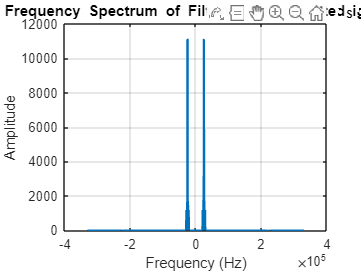

Filtered_Signal2 = filter(BandPassFilter2, Demodulated_Signal);

% Compute the spectrum of the Filtered Demodulated_Signal
N = length(Filtered_Signal2); 
freq = (-N/2:N/2-1) * (Fs_new / N); 
spectrumFiltered2 = fftshift(abs(fft(Filtered_Signal2))); 

% Plot the Filtered Demodulated_Signal in the frequency domain
figure;
plot(freq, spectrumFiltered2);
xlabel('Frequency (Hz)');
ylabel('Amplitude');
title('Frequency Spectrum of Filtered Demodulated_Signal');
grid on;

## Oscillator to shift from Wif to baseband

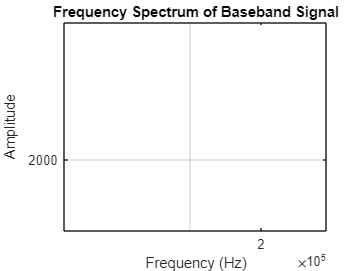

% Oscillator to shift from Wif to 0 Hz
carrier_osc2 = cos(2 * pi * Wif * t'); 

% Downconvert the filtered signal to baseband
Baseband_Signal = Filtered_Signal2 .* carrier_osc2;

% Compute the FFT of the baseband signal
N = length(Baseband_Signal); 
freq = (-N/2:N/2-1) * (Fs_new / N); 
spectrumBaseband = fftshift(abs(fft(Baseband_Signal))); 

% Plot the baseband signal in the frequency domain
figure;
plot(freq, spectrumBaseband);
xlabel('Frequency (Hz)');
ylabel('Amplitude');
title('Frequency Spectrum of Baseband Signal');
grid on;

## LPF at Baseband

F_pass = 22000; 
F_stop = 22000 + 3000; 

% Design the LPF
lpSpec = fdesign.lowpass('Fp,Fst,Ap,Ast', F_pass, F_stop, 1, 70, Fs_new);
LPF = design(lpSpec, 'equiripple'); % FIR low-pass filter

%fvtool(LPF);

## Baseband filtered signal & return original fs

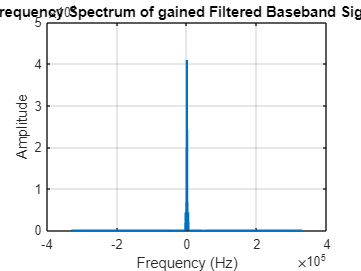

Filtered_Baseband_Signal = filter(LPF, Baseband_Signal);
Filtered_Baseband_Signal = Filtered_Baseband_Signal * 4;

% Compute the FFT of the Filtered_Baseband_Signal
N = length(Filtered_Baseband_Signal); 
freq = (-N/2:N/2-1) * (Fs_new / N); 
spectrumFilteredBaseband = fftshift(abs(fft(Filtered_Baseband_Signal))); 

% Plot the frequency spectrum
figure;
plot(freq, spectrumFilteredBaseband);
xlabel('Frequency (Hz)');
ylabel('Amplitude');
title('Frequency Spectrum of gained Filtered Baseband Signal');
grid on;

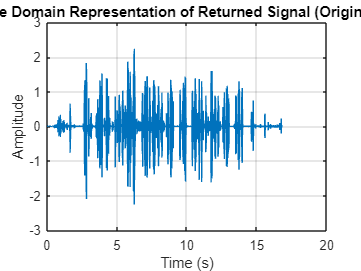



% Decimate the signal by a factor of 10 to return to the original Fs
Returned_Signal = downsample(Filtered_Baseband_Signal, 15);

% Time vector for the original sampling frequency
t_original = (0:length(Returned_Signal)-1) / Fs;

% Plot the returned signal in the time domain
figure;
plot(t_original, Returned_Signal);
xlabel('Time (s)');
ylabel('Amplitude');
title('Time Domain Representation of Returned Signal (Original Fs)');
grid on;


% Play the signal at the original Fs
sound(Returned_Signal, Fs);
